clc; close all; clear all;

# **DYNAMICS AND CONTROL OF VEHICLES AND ROBOTS**

## Example: Basic signal filtering

**University of Trento**

*A.Y. 2019/2020*

F. Biral

E. Pagot

## Intro

In this script the telemetry data from the P1 experimental vehicles are loaded. This Matlab Live Script can be used as the structure for your project script.

Click "Save as..." and save this script as .m in order to obtain a classic Matlab script.

## Load Vehicle Parameters

The script loads the vehicle main parameters in the `vehicle` struct. See the script `p1_parameters.m` for comments about parameters names and units.

p1_parameters

## Load Datasets

The following test are available.

**DATASET NAME DESCRIPTION**

RAMP_STEER_L Left-hand ramp steer 10 m/s

RAMP_STEER_R Right-hand ramp steer 10 m/s

SINE_STEER_IS Sine wave steering at increasing speeds

SP_100FT_CR_IS_CCW Steering pad 100 ft circle constant radius increasing speed counter-clockwise

SP_100FT_CR_IS_CW Steering pad 100 ft circle constant radius increasing speed clockwise

STRAIGHT_LINE_0 Straight line at constant speed

STRAIGHT_LINE_1 Straight line in one direction

STRAIGHT_LINE_2 Straight line in the opposite direction

STEP_STEER Step steer

load("Dataset/RAMP_STEER_L.mat");
telemetry = RAMP_STEER_L;

The loaded variable is a struct cointaing the following telemetry signals:

% DATA			UNITS		DESCRIPTION
% time                  s               acquisition time
% yaw			rad		yaw angle
% yaw_rate		rad/s 		yaw rate at COM
% roll			rad		roll at COM
% roll_rate		rad/s 		roll rate at COM
% long_vel		m/s 		longitudinal velocity of the COM
% lat_vel		m/s 		lateral velocity of the COM
% axG			m/s^2		longitudinal acceleration of the COM
% ayG			m/s^2 		lateral acceleration of the COM
% body_slip		rad		vehicle side slip angle (at COM)
% omega_FL		rad/s 		wheel angular speed
% omega_FR		rad/s 		wheel angular speed
% omega_RL		rad/s 		wheel angular speed
% omega_RR		rad/s 		wheel angular speed
% front_slip_angle      rad		equivalent (single track) slip angle at front axle
% rear_slip_angle       rad		equivalent (single track) slip angle at rear axle
% Fx_FL			N		tyre longitudinal force
% Fy_FL			N		tyre lateral force
% Fz_FL			N		tyre vertical force
% Fx_FR			N		tyre longitudinal force
% Fy_FR			N		tyre lateral force
% Fz_FR			N		tyre vertical force
% x_pos			m		COM position x coordinate (from GPS)
% y_pos			m		COM position y coordinate (from GPS)
% z_pos			m		COM position z coordinate or altitude (from GPS)
% delta_L		rad		steering angle of the front left wheel
% delta_R		rad		steering angle of the front right wheel
% delta_HW 		rad		handwheel steering angle

## Plot the lateral forces and the lateral acceleration

Firstly, we plot the signals we want to use for ours estimations/analysis, i.e. the vertical forces (we only have the ones at the front wheels) and the COM lateral acceleration.

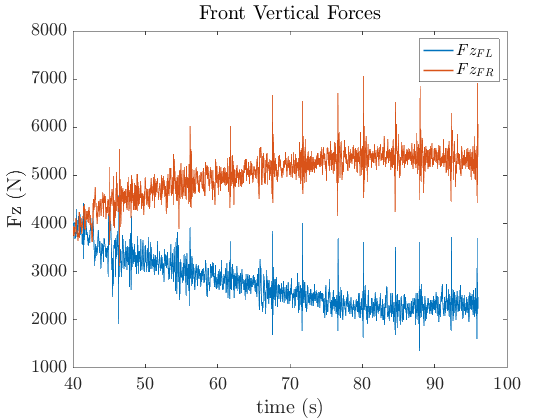

figure
plot(telemetry.time,telemetry.Fz_FL,'DisplayName','$Fz_{FL}$')
hold on
plot(telemetry.time,telemetry.Fz_FR,'DisplayName','$Fz_{FR}$')
xlabel('time (s)');ylabel('Fz (N)');
title('Front Vertical Forces');
legend

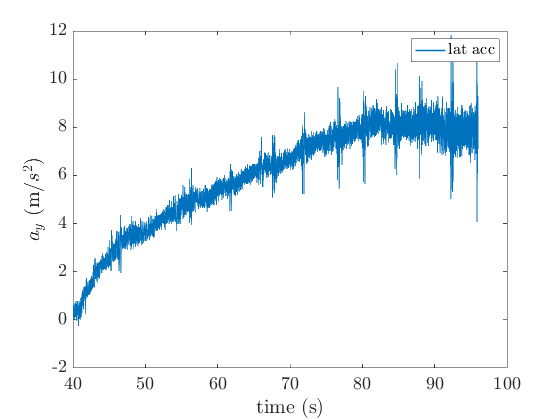


figure
plot(telemetry.time,telemetry.ayG,'DisplayName','lat acc')
xlabel('time (s)');ylabel('$a_y$ (m/$s^2$)');
legend

## Filter the signals using a low pass filter

The signals are quite noisy, so we must filter them. Let's compute the sampling time and the sampling frequencies of the telemetry.

Ts = telemetry.time(2) - telemetry.time(1);
disp("The sampling time is ts = " + Ts + "s.");

The sampling time is ts = 0.002s.



Fs = 1/Ts;
disp("The sampling frequency is fs = " + Fs + "Hz.");

The sampling frequency is fs = 500Hz.


Let's compute the Discrete Fourier Transform (DFT) of the lateral acceleration signal by using `fft`. 

Y = fft(telemetry.ayG);
L = length(telemetry.ayG);

P2 = abs(Y/L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;


And plot the spectrum of the signal.

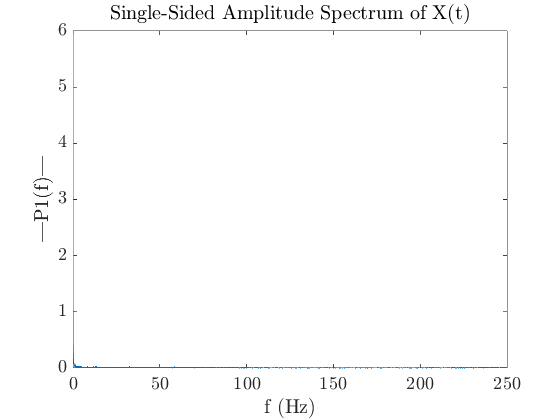

figure
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
hold on
xlabel('f (Hz)')
ylabel('|P1(f)|')

hold off

By zooming in, we can see that the largest components of the signal are at low frequencies and at medium and high frequencies there is only noise.

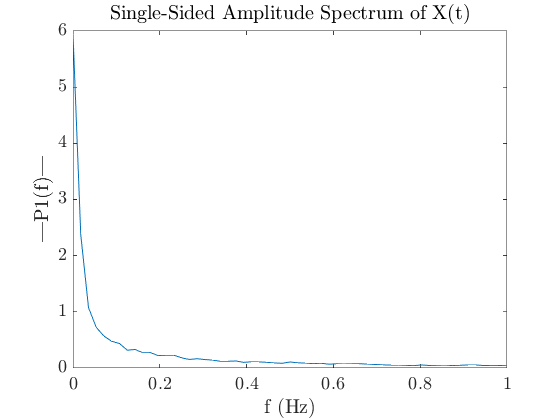

figure
plot(f,P1);
xlim([0 1]);
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Using a low pass filter the noise is (partially) filtered out. The cut-off frequency is 0.5Hz.

The Matlab function `lowpass` compensate for the delay (phase shift) introduced by the filter (you can also use the fuction `filtfilt,` while the function `filt` does not compensate for the delay).

ATTENTION: the telemetry in this example is from a *slow ramp steer, *so the lateral acceleration is increasing slowly (with a low frequency). If your data is for example from a *sine steer test* at 1Hz, low-pass filtering the lateral acceleration (or yaw rate, steer angle ect. ) with a cut-off frequency smaller than 2Hz can cause aliasing phenomena.

telemetry.ayG_filt = lowpass(telemetry.ayG,0.5,Fs,'Steepness',0.95);

## Plotting the filtered lateral acceleration

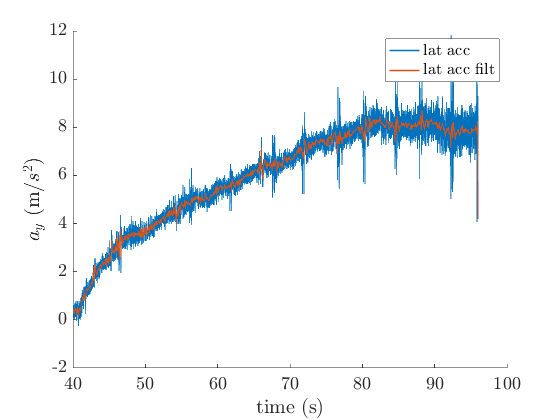


figure
hold on
plot(telemetry.time,telemetry.ayG,'DisplayName','lat acc')
plot(telemetry.time,telemetry.ayG_filt,'DisplayName','lat acc filt')
hold off
xlabel('time (s)');ylabel('$a_y$ (m/$s^2$)');
legend

## Filtering using `smooth`

The function `smooth` filters the signals using a moving average window. This function could be very useful to smooth very noisy signals. Nevertheless, using large averaging windows can introduce large delays in the filtered signal.

Let's smooth the vertical load signals using a moving average window of 500 samples (equivalent to Ts*500 = 1 second).

telemetry.Fz_FL_filt = smooth(telemetry.Fz_FL,500);
telemetry.Fz_FR_filt = smooth(telemetry.Fz_FR,500);

And compare the filtered signals with the original ones.

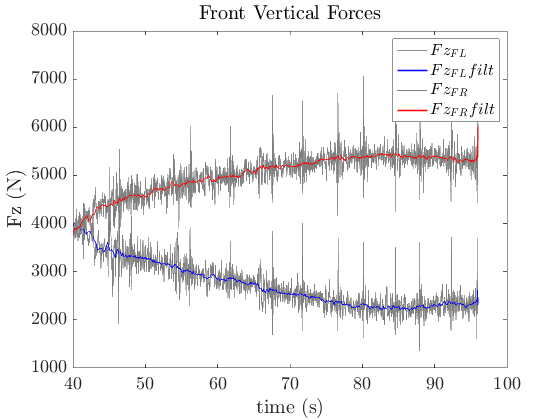

figure
plot(telemetry.time,telemetry.Fz_FL,'Color',[0.5 0.5 0.5],'DisplayName','$Fz_{FL}$','LineWidth',0.5)
hold on
plot(telemetry.time,telemetry.Fz_FL_filt,'b','DisplayName','$Fz_{FL} filt$')
plot(telemetry.time,telemetry.Fz_FR,'Color',[0.5 0.5 0.5],'DisplayName','$Fz_{FR}$','LineWidth',0.5)
plot(telemetry.time,telemetry.Fz_FR_filt,'r','DisplayName','$Fz_{FR} filt$')
xlabel('time (s)');ylabel('Fz (N)');
title('Front Vertical Forces');
legend